start_deg = 68;
end_deg = 98;
N = 150;

function y = EaseQubic(t, start_deg, end_deg)
    len = length(t);
    for i = 1:len
        if t(i) < 0.5
            y(i) = 4*t(i)^3;
        else
            y(i) = 0.5*(2*t(i)-2)^3 + 1;
        end
    end
    y = y.*(end_deg - start_deg) + start_deg;
end

function y = EaseSine(t, start_deg, end_deg)
    len = length(t);
    for i = 1:len
        y(i) = -0.5 * cos(pi*t(i)) + 0.5;
    end
    y = y.*(end_deg - start_deg) + start_deg;
end

time_long = linspace(0,1,N);
K=1;
time_short = linspace(0,1,N/K);
T = 50;
time_leg = linspace(0,1,N/2 + T)

time_leg =          0    0.0081    0.0161    0.0242    0.0323    0.0403    0.0484    0.0565    0.0645    0.0726    0.0806    0.0887    0.0968    0.1048    0.1129    0.1210    0.1290    0.1371    0.1452    0.1532    0.1613    0.1694    0.1774    0.1855    0.1935    0.2016    0.2097    0.2177    0.2258    0.2339    0.2419    0.2500    0.2581    0.2661    0.2742    0.2823    0.2903    0.2984    0.3065    0.3145    0.3226    0.3306    0.3387    0.3468    0.3548    0.3629    0.3710    0.3790    0.3871    0.3952


rest = N - 2*T

rest = 50


plt_cubic1 = EaseQubic(time_long, start_deg, end_deg)

plt_cubic1 =    68.0000   68.0000   68.0003   68.0010   68.0023   68.0045   68.0078   68.0124   68.0186   68.0264   68.0363   68.0483   68.0627   68.0797   68.0995   68.1224   68.1486   68.1782   68.2116   68.2488   68.2902   68.3360   68.3863   68.4414   68.5015   68.5668   68.6376   68.7140   68.7963   68.8847   68.9795   69.0807   69.1887   69.3037   69.4258   69.5553   69.6925   69.8375   69.9906   70.1519   70.3217   70.5002   70.6876   70.8842   71.0902   71.3057   71.5310   71.7663   72.0119   72.2679


plt_cubic2 = EaseQubic(time_short, end_deg, start_deg)

plt_cubic2 =    98.0000   98.0000   97.9997   97.9990   97.9977   97.9955   97.9922   97.9876   97.9814   97.9736   97.9637   97.9517   97.9373   97.9203   97.9005   97.8776   97.8514   97.8218   97.7884   97.7512   97.7098   97.6640   97.6137   97.5586   97.4985   97.4332   97.3624   97.2860   97.2037   97.1153   97.0205   96.9193   96.8113   96.6963   96.5742   96.4447   96.3075   96.1625   96.0094   95.8481   95.6783   95.4998   95.3124   95.1158   94.9098   94.6943   94.4690   94.2337   93.9881   93.7321


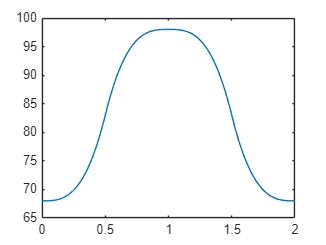

plot([time_long time_short/K + 1], [plt_cubic1 plt_cubic2])



sine1 = EaseSine(time_long, start_deg, end_deg)

sine1 =    68.0000   68.0033   68.0133   68.0300   68.0533   68.0833   68.1199   68.1631   68.2129   68.2693   68.3322   68.4016   68.4776   68.5600   68.6488   68.7440   68.8455   68.9533   69.0674   69.1876   69.3140   69.4465   69.5850   69.7295   69.8799   70.0361   70.1980   70.3657   70.5389   70.7178   70.9020   71.0917   71.2866   71.4868   71.6920   71.9023   72.1176   72.3376   72.5624   72.7919   73.0259   73.2643   73.5070   73.7540   74.0051   74.2602   74.5191   74.7818   75.0482   75.3181


sine2 = EaseSine(time_short, end_deg, start_deg)

sine2 =    98.0000   97.9967   97.9867   97.9700   97.9467   97.9167   97.8801   97.8369   97.7871   97.7307   97.6678   97.5984   97.5224   97.4400   97.3512   97.2560   97.1545   97.0467   96.9326   96.8124   96.6860   96.5535   96.4150   96.2705   96.1201   95.9639   95.8020   95.6343   95.4611   95.2822   95.0980   94.9083   94.7134   94.5132   94.3080   94.0977   93.8824   93.6624   93.4376   93.2081   92.9741   92.7357   92.4930   92.2460   91.9949   91.7398   91.4809   91.2182   90.9518   90.6819


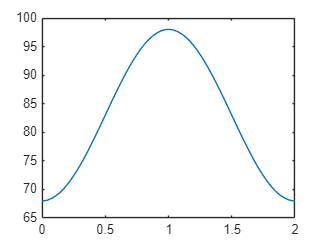

sine_leg = circshift([linspace(90,90,rest) EaseSine(time_leg, 90, 75) EaseSine(time_leg, 75, 90)], T);
plot([time_long time_short/K + 1], [sine1 sine2])

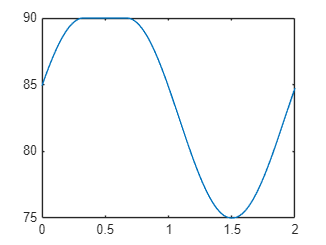

plot([linspace(0,2,2*N)], sine_leg)


% Set final points
data = reshape([[sine1 sine2]; sine_leg], 1, []);
points = round(data, 1)

points =    68.0000   84.9000   68.0000   85.1000   68.0000   85.3000   68.0000   85.5000   68.1000   85.6000   68.1000   85.8000   68.1000   86.0000   68.2000   86.1000   68.2000   86.3000   68.3000   86.5000   68.3000   86.6000   68.4000   86.8000   68.5000   86.9000   68.6000   87.1000   68.6000   87.2000   68.7000   87.4000   68.8000   87.5000   69.0000   87.7000   69.1000   87.8000   69.2000   87.9000   69.3000   88.1000   69.4000   88.2000   69.6000   88.3000   69.7000   88.4000   69.9000   88.5000



% Create commands

for i = 1:length(points)
    if i == 1
        fprintf('V1\nE0\nS0:%g\nS4:%g\nW100\n----------\n', points(1), points(2))
    end
    fprintf('S%d:%g\n', mod(i-1,2)*4, points(i));
end

V1
E0
S0:68
S4:84.9
W100
----------


S0:68
S4:84.9
S0:68
S4:85.1
S0:68
S4:85.3
S0:68
S4:85.5
S0:68.1
S4:85.6
S0:68.1
S4:85.8
S0:68.1
S4:86
S0:68.2
S4:86.1
S0:68.2
S4:86.3
S0:68.3
S4:86.5
S0:68.3
S4:86.6
S0:68.4
S4:86.8
S0:68.5
S4:86.9
S0:68.6
S4:87.1
S0:68.6
S4:87.2
S0:68.7
S4:87.4
S0:68.8
S4:87.5
S0:69
S4:87.7
S0:69.1
S4:87.8
S0:69.2
S4:87.9
S0:69.3
S4:88.1
S0:69.4
S4:88.2
S0:69.6
S4:88.3
S0:69.7
S4:88.4
S0:69.9
S4:88.5
S0:70
S4:88.7
S0:70.2
S4:88.8
S0:70.4
S4:88.9
S0:70.5
S4:89
S0:70.7
S4:89.1
S0:70.9
S4:89.1
S0:71.1
S4:89.2
S0:71.3
S4:89.3
S0:71.5
S4:89.4
S0:71.7
S4:89.5
S0:71.9
S4:89.5
S0:72.1
S4:89.6
S0:72.3
S4:89.7
S0:72.6
S4:89.7
S0:72.8
S4:89.8
S0:73
S4:89.8
S0:73.3
S4:89.8
S0:73.5
S4:89.9
S0:73.8
S4:89.9
S0:74
S4:89.9
S0:74.3
S4:90
S0:74.5
S4:90
S0:74.8
S4:90
S0:75
S4:90
S0:75.3
S4:90
S0:75.6
S4:90
S0:75.9
S4:90
S0:76.1
S4:90
S0:76.4
S4:90
S0:76.7
S4:90
S0:77
S4:90
S0:77.3
S4:90
S0:77.6
S4:90
S0:77.9
S4:90
S0:78.2
S4:90
S0:78.5
S4:90
S0:78.8
S4:90
S0:79.1
S4:90
S0:79.4
S4:90
S0:79.7
S4:90
S0:80
S4:90
S0:80.3
S4:9